#### Exercise-1: 

#### Construct an analog signal y with A = 5, f = 20 Hz, T=1/f sec, t=0:T/50:2T using the function y=A*sin(2*pi*f*t). Write Matlab code for 10 bit analog-to-digital conversion and  reconstruction of analog signal using sampling rate of

clc; close all; clear;
b=10; % number of bits/sample;
A=5; % Amplitude of analog signal 
F = 20; %% Frequency of the analog signal
T = 1/F; %% Period of the analog signal
tmin = 0; tmax = 2*T; %% The signal is for 2 period
dt = T/50; %%
t = tmin:dt:tmax;
xt = A*sin(2*pi*F*t);

#### (a) Fs = 40 samples/second

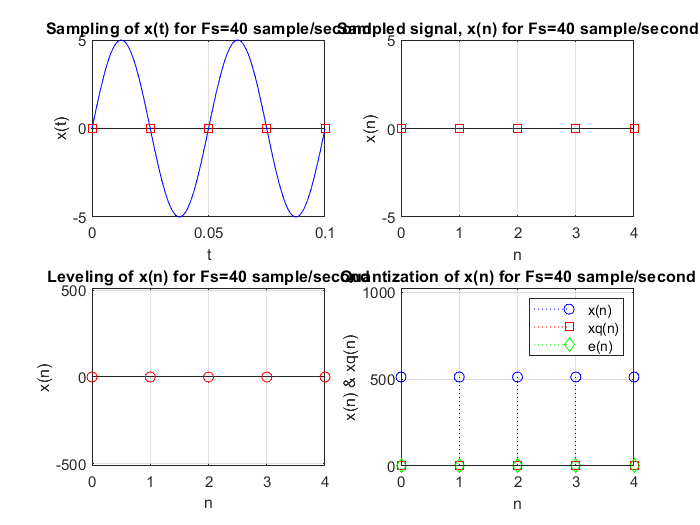

Fs = 40;
dts = 1/Fs; 
ts = tmin:dts:tmax;
xs = A*sin(2*pi*F*ts);
n=0:1:(length(ts)-1);
del=2*A/(2^b-1); % quantization step
xL=(xs/del); %% Laveling according to quantization level
L=2^b-1; %% No. of quantization level
xq=round(xL-min(xL)); %% Leveling & quantization
e=xq-xL; % Quantization error
xd=dec2bin(xq,b); 
xtr=(bin2dec(xd)-L/2)*del;
figure;
subplot(2,2,1)
plot(t,xt,'-b');
hold on
stem(ts,xs,'rs');
title('Sampling of x(t) for Fs=40 sample/second')
xlabel('t')
ylabel('x(t)')
ylim([-A A])
grid on
subplot(2,2,2)
stem(n,xs,'rs')
xlabel('n')
ylabel('x(n)')
title('Sampled signal, x(n) for Fs=40 sample/second')
ylim([-A A])
grid on
subplot(2,2,3)
stem(n,xL,'r')
xlabel('n')
ylabel('x(n)')
title('Leveling of x(n) for Fs=40 sample/second')
ylim([-L/2 L/2])
grid on
subplot(2,2,4)
stem(n,xL+L/2,':bo')
hold on
stem(n,xq,':rs')
hold on
stem(n,e,':gd')
xlabel('n')
ylabel('x(n) & xq(n)')
title('Quantization of x(n) for Fs=40 sample/second')
legend('x(n)','xq(n)','e(n)')
ylim([0 L])
grid on

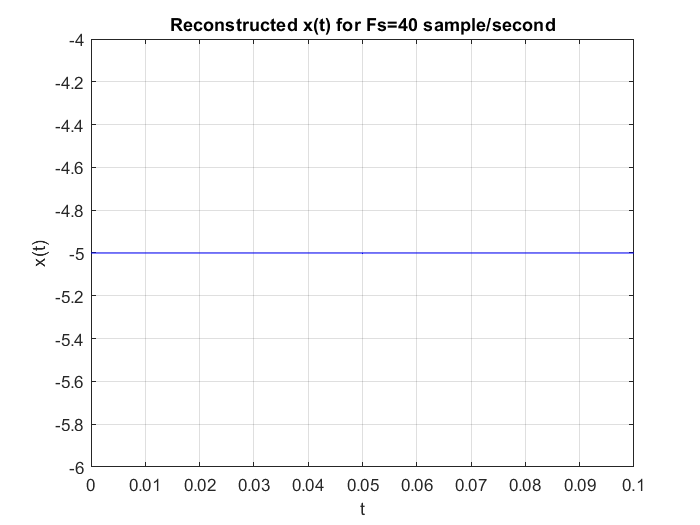

figure;
plot(ts,xtr,'-b')
xlabel('t')
ylabel('x(t)')
title('Reconstructed x(t) for Fs=40 sample/second')
grid on

#### (b) Fs = 50  samples/second

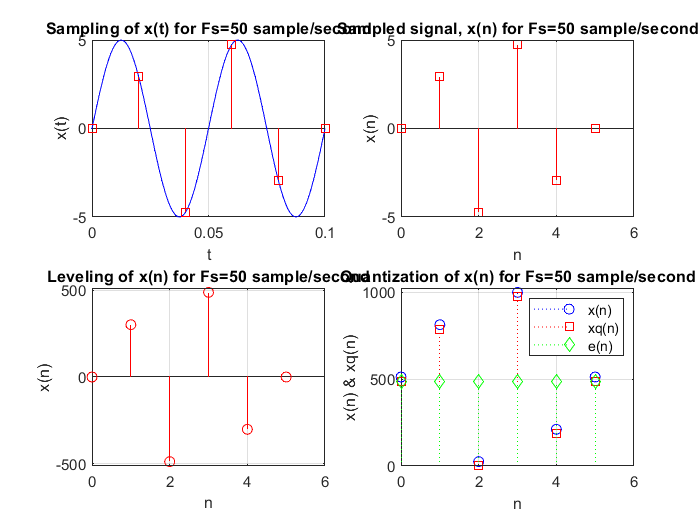

Fs = 50;
dts = 1/Fs; 
ts = tmin:dts:tmax;
xs = A*sin(2*pi*F*ts);
n=0:1:(length(ts)-1);
del=2*A/(2^b-1); % quantization step
xL=(xs/del); %% Laveling according to quantization level
L=2^b-1; %% No. of quantization level
xq=round(xL-min(xL)); %% Leveling & quantization
e=xq-xL; % Quantization error
xd=dec2bin(xq,b); 
xtr=(bin2dec(xd)-L/2)*del;
figure;
subplot(2,2,1)
plot(t,xt,'-b');
hold on
stem(ts,xs,'rs');
title('Sampling of x(t) for Fs=50 sample/second')
xlabel('t')
ylabel('x(t)')
ylim([-A A])
grid on
subplot(2,2,2)
stem(n,xs,'rs')
xlabel('n')
ylabel('x(n)')
title('Sampled signal, x(n) for Fs=50 sample/second')
ylim([-A A])
grid on
subplot(2,2,3)
stem(n,xL,'r')
xlabel('n')
ylabel('x(n)')
title('Leveling of x(n) for Fs=50 sample/second')
ylim([-L/2 L/2])
grid on
subplot(2,2,4)
stem(n,xL+L/2,':bo')
hold on
stem(n,xq,':rs')
hold on
stem(n,e,':gd')
xlabel('n')
ylabel('x(n) & xq(n)')
title('Quantization of x(n) for Fs=50 sample/second')
legend('x(n)','xq(n)','e(n)')
ylim([0 L])
grid on

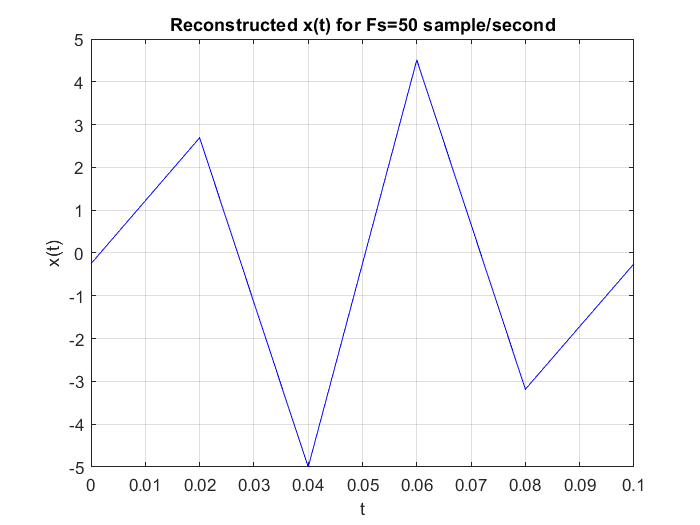

figure;
plot(ts,xtr,'-b')
xlabel('t')
ylabel('x(t)')
title('Reconstructed x(t) for Fs=50 sample/second')
grid on

#### (c) Fs = 100 samples/second

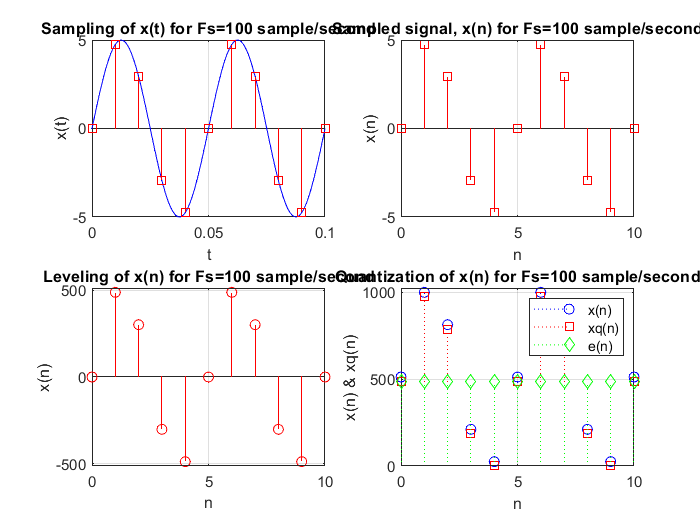

Fs = 100;
dts = 1/Fs; 
ts = tmin:dts:tmax;
xs = A*sin(2*pi*F*ts);
n=0:1:(length(ts)-1);
del=2*A/(2^b-1); % quantization step
xL=(xs/del); %% Laveling according to quantization level
L=2^b-1; %% No. of quantization level
xq=round(xL-min(xL)); %% Leveling & quantization
e=xq-xL; % Quantization error
xd=dec2bin(xq,b); 
xtr=(bin2dec(xd)-L/2)*del;
figure;
subplot(2,2,1)
plot(t,xt,'-b');
hold on
stem(ts,xs,'rs');
title('Sampling of x(t) for Fs=100 sample/second')
xlabel('t')
ylabel('x(t)')
ylim([-A A])
grid on
subplot(2,2,2)
stem(n,xs,'rs')
xlabel('n')
ylabel('x(n)')
title('Sampled signal, x(n) for Fs=100 sample/second')
ylim([-A A])
grid on
subplot(2,2,3)
stem(n,xL,'r')
xlabel('n')
ylabel('x(n)')
title('Leveling of x(n) for Fs=100 sample/second')
ylim([-L/2 L/2])
grid on
subplot(2,2,4)
stem(n,xL+L/2,':bo')
hold on
stem(n,xq,':rs')
hold on
stem(n,e,':gd')
xlabel('n')
ylabel('x(n) & xq(n)')
title('Quantization of x(n) for Fs=100 sample/second')
legend('x(n)','xq(n)','e(n)')
ylim([0 L])
grid on

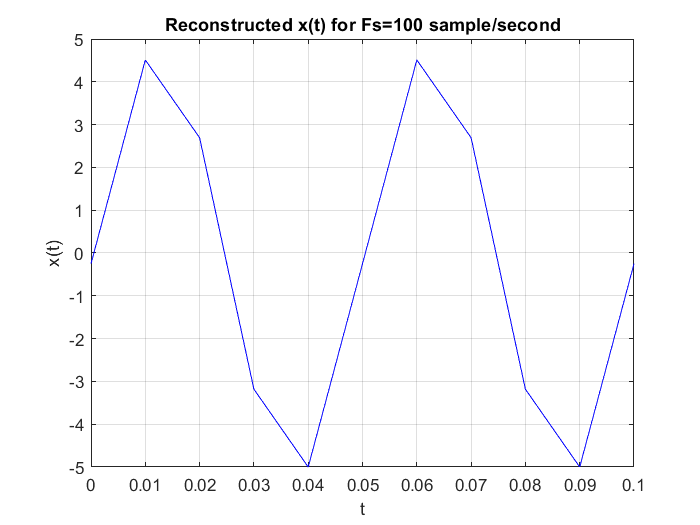

figure;
plot(ts,xtr,'-b')
xlabel('t')
ylabel('x(t)')
title('Reconstructed x(t) for Fs=100 sample/second')
grid on

#### (d) Fs = 200 samples/second

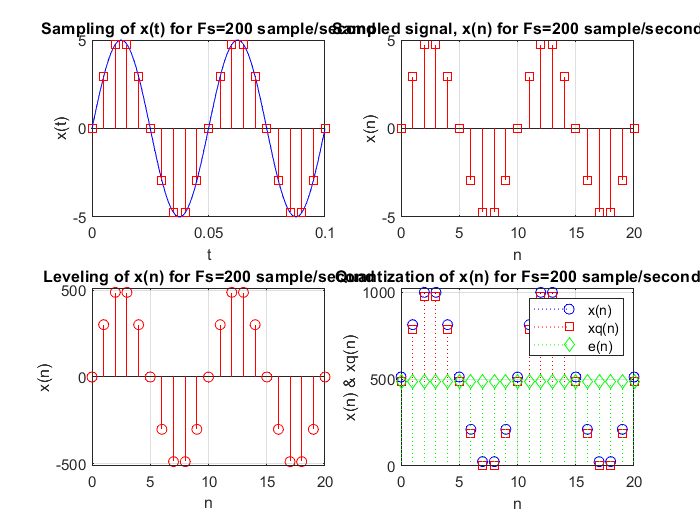

Fs = 200;
dts = 1/Fs; 
ts = tmin:dts:tmax;
xs = A*sin(2*pi*F*ts);
n=0:1:(length(ts)-1);
del=2*A/(2^b-1); % quantization step
xL=(xs/del); %% Laveling according to quantization level
L=2^b-1; %% No. of quantization level
xq=round(xL-min(xL)); %% Leveling & quantization
e=xq-xL; % Quantization error
xd=dec2bin(xq,b); 
xtr=(bin2dec(xd)-L/2)*del;
figure;
subplot(2,2,1)
plot(t,xt,'-b');
hold on
stem(ts,xs,'rs');
title('Sampling of x(t) for Fs=200 sample/second')
xlabel('t')
ylabel('x(t)')
ylim([-A A])
grid on
subplot(2,2,2)
stem(n,xs,'rs')
xlabel('n')
ylabel('x(n)')
title('Sampled signal, x(n) for Fs=200 sample/second')
ylim([-A A])
grid on
subplot(2,2,3)
stem(n,xL,'r')
xlabel('n')
ylabel('x(n)')
title('Leveling of x(n) for Fs=200 sample/second')
ylim([-L/2 L/2])
grid on
subplot(2,2,4)
stem(n,xL+L/2,':bo')
hold on
stem(n,xq,':rs')
hold on
stem(n,e,':gd')
xlabel('n')
ylabel('x(n) & xq(n)')
title('Quantization of x(n) for Fs=200 sample/second')
legend('x(n)','xq(n)','e(n)')
ylim([0 L])
grid on

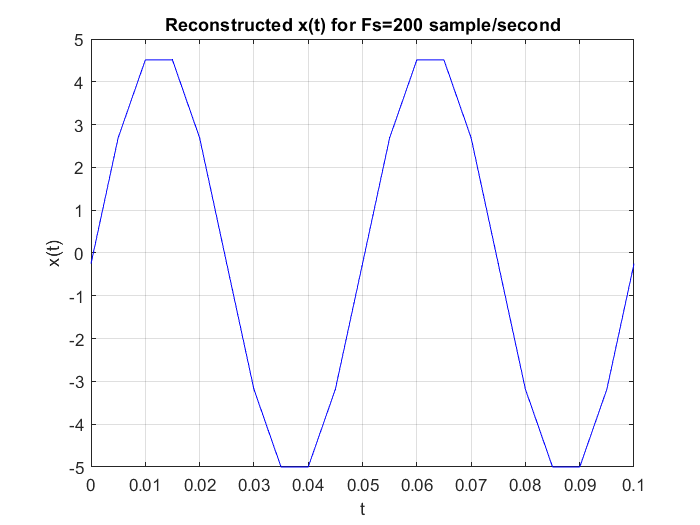

figure;
plot(ts,xtr,'-b')
xlabel('t')
ylabel('x(t)')
title('Reconstructed x(t) for Fs=200 sample/second')
grid on

#### Exercise-2 

#### Construct an analog signal y with A = 5, f = 20 Hz, T=1/f sec, t=0:T/50:2T using the function y=A*cos(2*pi*f*t). Write Matlab code for analog-to-digital conversion and reconstruction of  analog signal

clc; close all; clear;
b=10; % number of bits/sample;
A=5; % Amplitude of analog signal 
F = 20; %% Frequency of the analog signal
T = 1/F; %% Period of the analog signal
tmin = 0; tmax = 2*T; %% The signal is for 2 period
dt = T/50; %%
t = tmin:dt:tmax;
xt = A*sin(2*pi*F*t);

#### (a) Fs = 8 samples/second

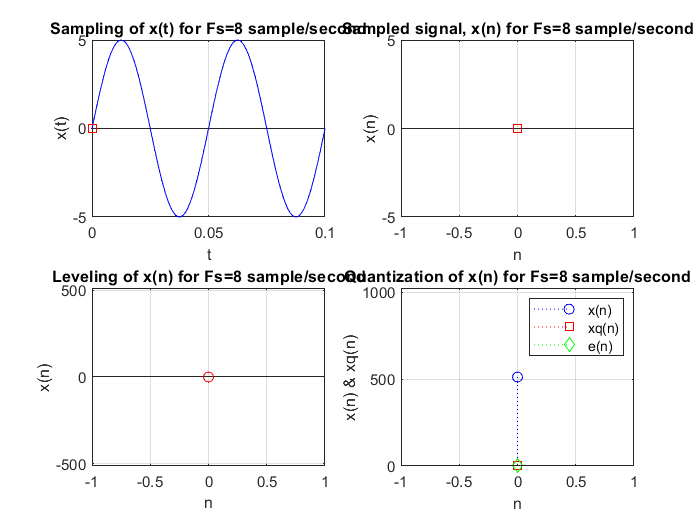

Fs = 8;
dts = 1/Fs; 
ts = tmin:dts:tmax;
xs = A*sin(2*pi*F*ts);
n=0:1:(length(ts)-1);
del=2*A/(2^b-1); % quantization step
xL=(xs/del); %% Laveling according to quantization level
L=2^b-1; %% No. of quantization level
xq=round(xL-min(xL)); %% Leveling & quantization
e=xq-xL; % Quantization error
xd=dec2bin(xq,b); 
xtr=(bin2dec(xd)-L/2)*del;
figure;
subplot(2,2,1)
plot(t,xt,'-b');
hold on
stem(ts,xs,'rs');
title('Sampling of x(t) for Fs=8 sample/second')
xlabel('t')
ylabel('x(t)')
ylim([-A A])
grid on
subplot(2,2,2)
stem(n,xs,'rs')
xlabel('n')
ylabel('x(n)')
title(['Sampled signal, x(n) for Fs=8 sample/second'])
ylim([-A A])
grid on
subplot(2,2,3)
stem(n,xL,'r')
xlabel('n')
ylabel('x(n)')
title('Leveling of x(n) for Fs=8 sample/second')
ylim([-L/2 L/2])
grid on
subplot(2,2,4)
stem(n,xL+L/2,':bo')
hold on
stem(n,xq,':rs')
hold on
stem(n,e,':gd')
xlabel('n')
ylabel('x(n) & xq(n)')
title('Quantization of x(n) for Fs=8 sample/second')
legend('x(n)','xq(n)','e(n)')
ylim([0 L])
grid on

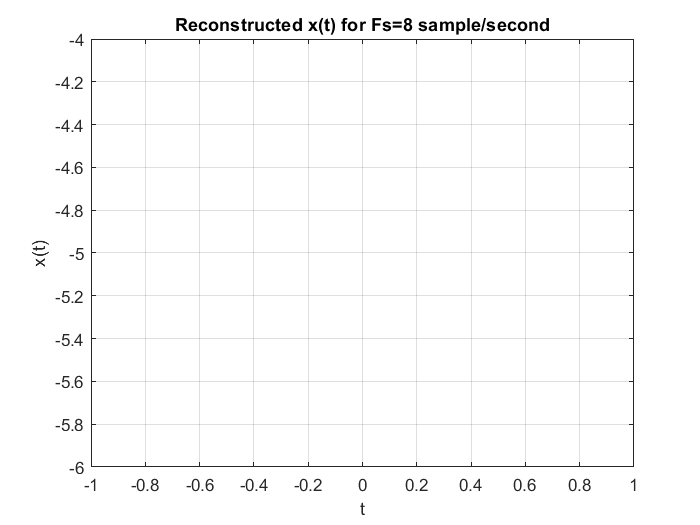

figure;
plot(ts,xtr,'-b')
xlabel('t')
ylabel('x(t)')
title('Reconstructed x(t) for Fs=8 sample/second')
grid on

#### (b) Fs = 16  samples/second

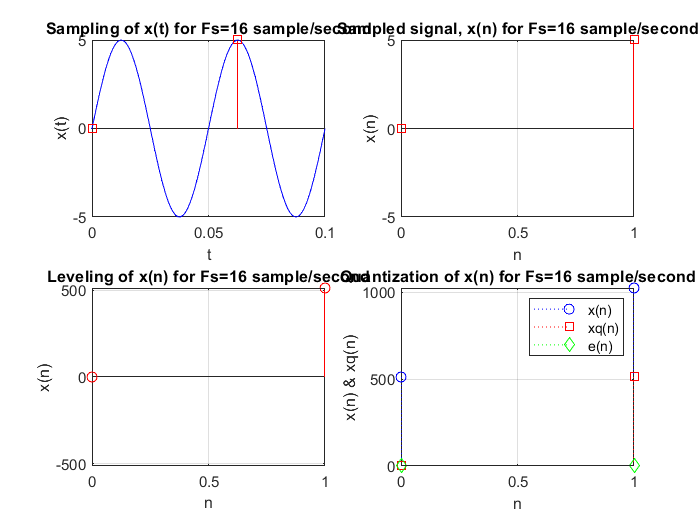

Fs = 16;
dts = 1/Fs; 
ts = tmin:dts:tmax;
xs = A*sin(2*pi*F*ts);
n=0:1:(length(ts)-1);
del=2*A/(2^b-1); % quantization step
xL=(xs/del); %% Laveling according to quantization level
L=2^b-1; %% No. of quantization level
xq=round(xL-min(xL)); %% Leveling & quantization
e=xq-xL; % Quantization error
xd=dec2bin(xq,b); 
xtr=(bin2dec(xd)-L/2)*del;
figure;
subplot(2,2,1)
plot(t,xt,'-b');
hold on
stem(ts,xs,'rs');
title('Sampling of x(t) for Fs=16 sample/second')
xlabel('t')
ylabel('x(t)')
ylim([-A A])
grid on
subplot(2,2,2)
stem(n,xs,'rs')
xlabel('n')
ylabel('x(n)')
title('Sampled signal, x(n) for Fs=16 sample/second')
ylim([-A A])
grid on
subplot(2,2,3)
stem(n,xL,'r')
xlabel('n')
ylabel('x(n)')
title('Leveling of x(n) for Fs=16 sample/second')
ylim([-L/2 L/2])
grid on
subplot(2,2,4)
stem(n,xL+L/2,':bo')
hold on
stem(n,xq,':rs')
hold on
stem(n,e,':gd')
xlabel('n')
ylabel('x(n) & xq(n)')
title('Quantization of x(n) for Fs=16 sample/second')
legend('x(n)','xq(n)','e(n)')
ylim([0 L])
grid on

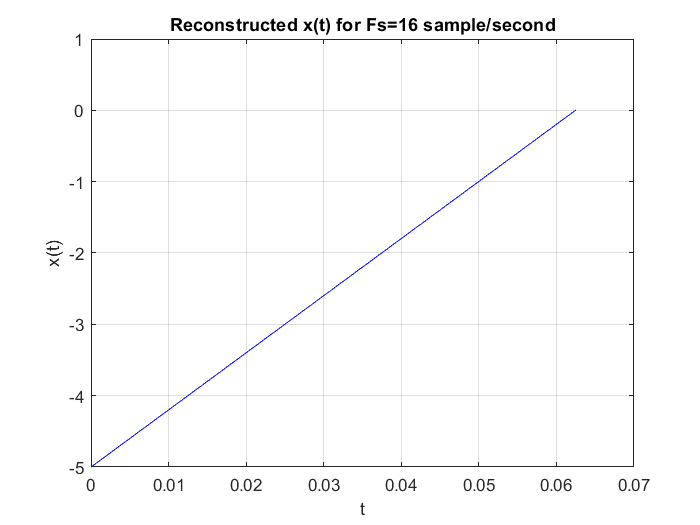

figure;
plot(ts,xtr,'-b')
xlabel('t')
ylabel('x(t)')
title('Reconstructed x(t) for Fs=16 sample/second')
grid on

#### (c) Fs = 32 samples/second

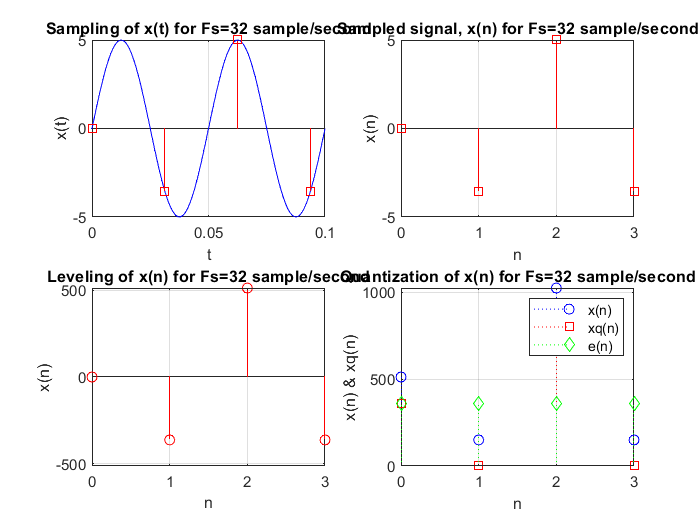

Fs = 32;
dts = 1/Fs; 
ts = tmin:dts:tmax;
xs = A*sin(2*pi*F*ts);
n=0:1:(length(ts)-1);
del=2*A/(2^b-1); % quantization step
xL=(xs/del); %% Laveling according to quantization level
L=2^b-1; %% No. of quantization level
xq=round(xL-min(xL)); %% Leveling & quantization
e=xq-xL; % Quantization error
xd=dec2bin(xq,b); 
xtr=(bin2dec(xd)-L/2)*del;
figure;
subplot(2,2,1)
plot(t,xt,'-b');
hold on
stem(ts,xs,'rs');
title('Sampling of x(t) for Fs=32 sample/second')
xlabel('t')
ylabel('x(t)')
ylim([-A A])
grid on
subplot(2,2,2)
stem(n,xs,'rs')
xlabel('n')
ylabel('x(n)')
title('Sampled signal, x(n) for Fs=32 sample/second')
ylim([-A A])
grid on
subplot(2,2,3)
stem(n,xL,'r')
xlabel('n')
ylabel('x(n)')
title('Leveling of x(n) for Fs=32 sample/second')
ylim([-L/2 L/2])
grid on
subplot(2,2,4)
stem(n,xL+L/2,':bo')
hold on
stem(n,xq,':rs')
hold on
stem(n,e,':gd')
xlabel('n')
ylabel('x(n) & xq(n)')
title('Quantization of x(n) for Fs=32 sample/second')
legend('x(n)','xq(n)','e(n)')
ylim([0 L])
grid on

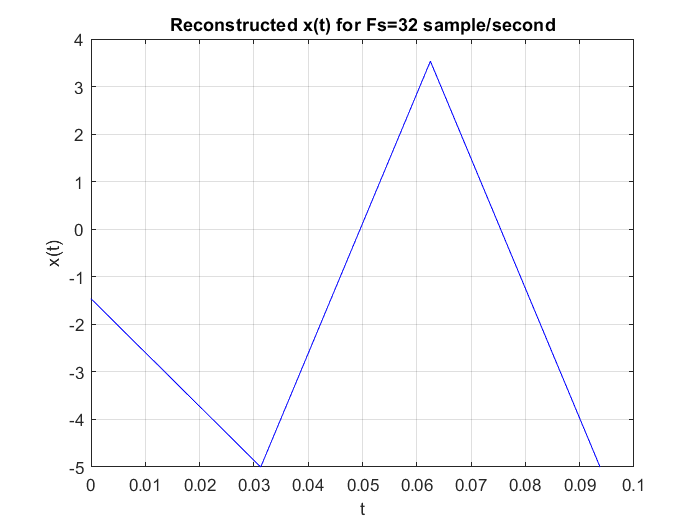

figure;
plot(ts,xtr,'-b')
xlabel('t')
ylabel('x(t)')
title('Reconstructed x(t) for Fs=32 sample/second')
grid on

#### (d) Fs = 1024 samples/second

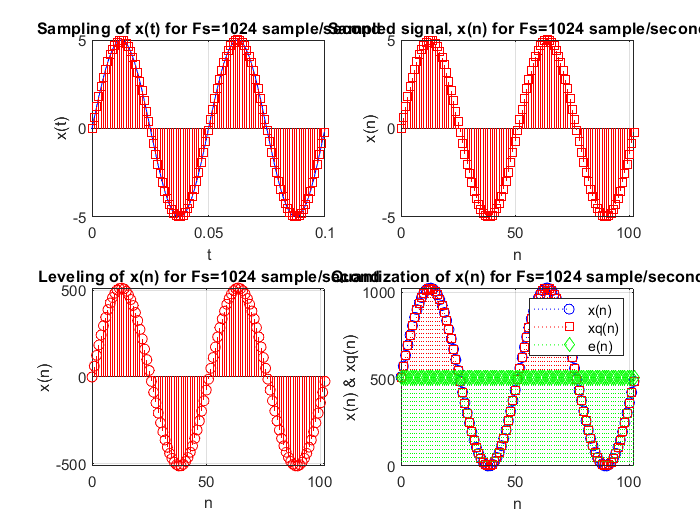

Fs = 1024;
dts = 1/Fs; 
ts = tmin:dts:tmax;
xs = A*sin(2*pi*F*ts);
n=0:1:(length(ts)-1);
del=2*A/(2^b-1); % quantization step
xL=(xs/del); %% Laveling according to quantization level
L=2^b-1; %% No. of quantization level
xq=round(xL-min(xL)); %% Leveling & quantization
e=xq-xL; % Quantization error
xd=dec2bin(xq,b); 
xtr=(bin2dec(xd)-L/2)*del;
figure;
subplot(2,2,1)
plot(t,xt,'-b');
hold on
stem(ts,xs,'rs');
title('Sampling of x(t) for Fs=1024 sample/second')
xlabel('t')
ylabel('x(t)')
ylim([-A A])
grid on
subplot(2,2,2)
stem(n,xs,'rs')
xlabel('n')
ylabel('x(n)')
title('Sampled signal, x(n) for Fs=1024 sample/second')
ylim([-A A])
grid on
subplot(2,2,3)
stem(n,xL,'r')
xlabel('n')
ylabel('x(n)')
title('Leveling of x(n) for Fs=1024 sample/second')
ylim([-L/2 L/2])
grid on
subplot(2,2,4)
stem(n,xL+L/2,':bo')
hold on
stem(n,xq,':rs')
hold on
stem(n,e,':gd')
xlabel('n')
ylabel('x(n) & xq(n)')
title('Quantization of x(n) for Fs=1024 sample/second')
legend('x(n)','xq(n)','e(n)')
ylim([0 L])
grid on

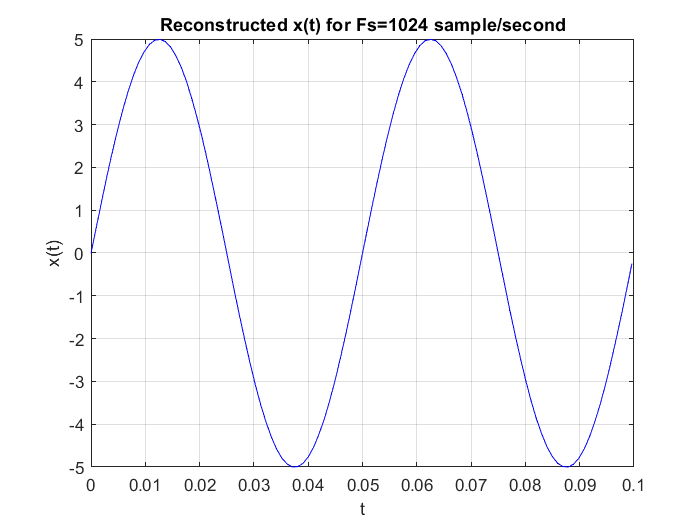

figure;
plot(ts,xtr,'-b')
xlabel('t')
ylabel('x(t)')
title('Reconstructed x(t) for Fs=1024 sample/second')
grid on

#### Exercise-3 

#### Construct an analog signal y with A=5, f=5 Hz, T=1/f sec, t=0:T/100:5T using the function y=A*sin(2*pi*f*t). Write Matlab code for analog-to-digital conversion and determine SQNR  for using different bits/sample of b=1 to 16. Also draw a plot to show the graph of b vs  SQNR. You should use for loop to compute SQNR.

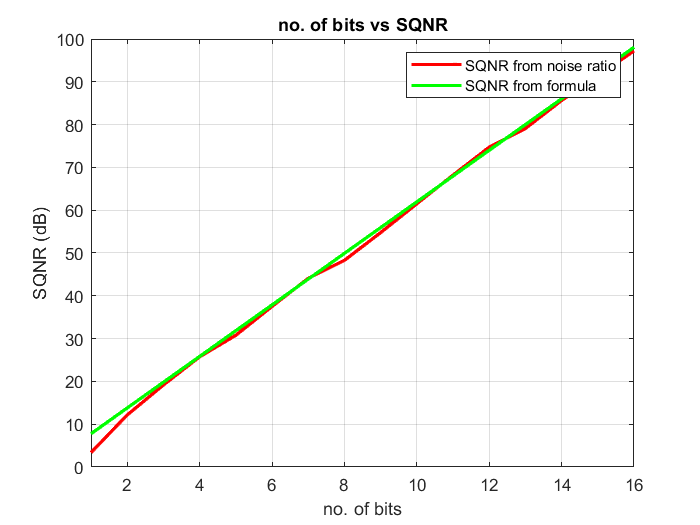

clc; close all; clear;
b=10; % number of bits/sample;
A=5; % Amplitude of analog signal 
F = 5; %% Frequency of the analog signal
T = 1/F; %% Period of the analog signal
tmin = 0; tmax = 5*T; %% The signal is for 2 period
dt = T/100; %%
t = tmin:dt:tmax;
xt = A*sin(2*pi*F*t);
figure;
plot(t,xt,'-b');
hold on
title('Analog signal x(t)')
xlabel('t')
ylabel('x(t)')
ylim([-A-1 A+1])
grid on

clc; clear; close;
N=16; % max no. of bits
sqnr = zeros(N, 1); % initialising sqnr vector
b = 1:1:N;
for i=b
    A = 5; % amplitude
    f = 5; % frequency
    T = 1/f; % time period

    tmin = 0;
    tmax = 5*T;
    dt = T/100;
    t = tmin:dt:tmax; % time range
    xt = A*sin(2*pi*f*t); % analog signal

    % Sampling
    Fs = 400; % sampling rate
    dts = 1/Fs;
    ts = tmin:dts:tmax;
    xs = A*sin(2*pi*f*ts);
    n = 0:1:length(ts)-1;
    
    ps = sum(xs.^2)/length(xs); 
    L = 2^i - 1; % no. of levels
    del = 2 * A / L; % quantisation step
    xl = xs/del; % leveling
    xq = round(xl-min(xl)); % quantisation
    e = (xq-L/2)*del - xs; % quantisation error
    pe = sum(e.^2) / length(e); % quantisation noise power
    sqnr(i) = 10*log10(ps/pe);    
end
sqrn_theory = 1.76+6.02*b;

figure;
plot(b, sqnr,'r','LineWidth',2)
hold on;
plot(b, sqrn_theory,'g','LineWidth',2)
xlabel('no. of bits')
ylabel('SQNR (dB)')
title('no. of bits vs SQNR')
legend('SQNR from noise ratio','SQNR from formula');
xlim([1 16])
grid on